## fitrnet() implementation

% here is an exmaple for training the neural network for open circuit
% voltage using fitrnet()

NN_voc = fitrnet(input_gen,output_isc,"OptimizeHyperparameters","auto", ...
    "HyperparameterOptimizationOptions",struct("AcquisitionFunctionName", ...
    "expected-improvement-plus"));

|============================================================================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |  Activations |  Standardize |       Lambda |            LayerSizes |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |              |              |                       |
|============================================================================================================================================|
|    1 | Best   |      6.1564 |      100.28 |      6.1564 |      6.1564 |      sigmoid |        false |     0.014197 |  131                  |
|    2 | Best   |      5.9848 |      36.267 |      5.9848 |      5.9916 |         relu |         true |     0.068226 | [ 19  57]             |
|    3 | Accept |      8.4744 |     0.60793 |      5.9848 |       6.057 |      sigmoid |        false |       1.2492 | [  2  10]             |


% get predicted result
predicted_isc = predict(NN_voc, input_test_gen);

% calculate and display the MSE for each jparameter
mse_value = mean((predicted_voc - output_test_voc).^2);
disp(['Mean Squared Error for voc:' num2str(mse_value)]);

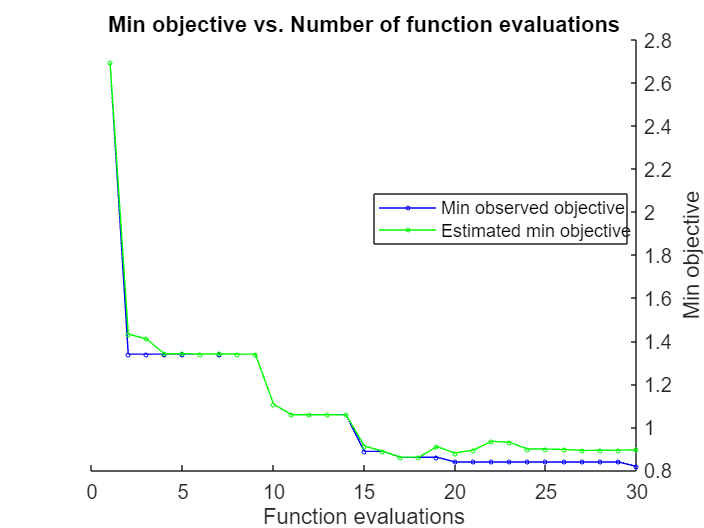

% plot the predicted vs actual value graph
predicted_voc = predict(NN_voc, input_test_gen);
figure;
scatter(output_test_voc, predicted_voc, 'filled');
xlabel('Actual Values of voc');
ylabel('Predicted Valuesn of voc');
title(['Actual vs Predicted Values for voc']);
grid on;

% Add a line for y = x
hold on;
plot([min(output_test_voc), max(output_test_voc)], ...
    [min(output_test_voc), max(output_test_voc)], 'r--');

hold off;

% saves the neural network
outputDir = "single_output_NN_history";
outputFile = fullfile(outputDir, "NN_voc.mat");
save(outputFile, "NN_voc")